# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.7 多个Y轴

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

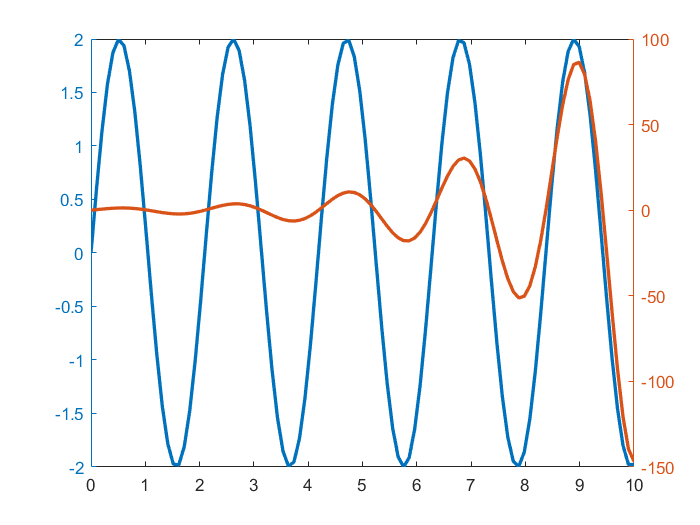

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% yyaxis 官方帮助文档 demo
figure;
x = linspace(0, 10, 100);
y1 = 2*sin(3*x);
y2 = sin(3*x) .* exp(0.5*x);
yyaxis left
plot(x, y1, 'LineWidth', 2);
yyaxis right
plot(x, y2, 'LineWidth', 2);

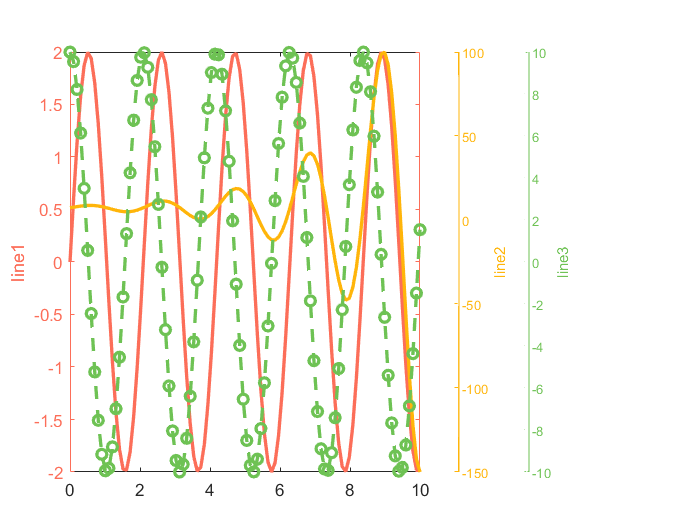

% 三个纵坐标演示，更多纵坐标可以按照此方法类推
figure;
y3 = 10*cos(3*x);
% 控制 aies 的大小和位置，注意是相对于figure的，范围为[0, 1]
% 三条线绘制到一起，注意数据都标准化到 y1 范围
maxY1 = max(y1);
maxY2 = max(y2);
maxY3 = max(y3);
minY1 = min(y1);
minY2 = min(y2);
minY3 = min(y3);
newY2 = (y2 - minY2)/(maxY2 - minY2);   % 归一化
newY2 = newY2*(maxY1 - minY1) + minY1;  % 反归一化
newY3 = (y3 - minY3)/(maxY3 - minY3);
newY3 = newY3*(maxY1 - minY1) + minY1;
% 画线
h1 = axes('position', [0.1 0.1 0.5 0.8]);  
plot(x, y1, 'Color', all_colors(1, :), 'LineWidth', 2);
hold on
plot(x, newY2, 'Color', all_colors(2, :), 'LineWidth', 2);
plot(x, newY3, 'o--', 'Color', all_colors(3, :), 'LineWidth', 2);
hold off
ylabel('line1');
h1.YColor = all_colors(1, :);
% 绘制另外两个空的坐标轴
h2 = axes('position', [0.65 0.1 0.005 0.8]); 
% 重复绘制，曲线颜色用白色，和figure背景色一致，看不出来即可
plot(x, y2, 'w')
% 颜色，位置，曲线标签
set(h2, 'ycolor', all_colors(2, :), 'yaxislocation', 'right', 'xtick', [])
% 边界显示不清楚，所以画一条线
hold on
limX2 = get(h2, 'Xlim');
limY2 = get(h2, 'Ylim');
plot([limX2(2), limX2(2)], limY2, 'Color', all_colors(2, :));
hold off
% 取消边框
box off
ylabel('line2');
%
h3 = axes('position', [0.75 0.1 0.005 0.8]); 
plot(x, y3, 'w')
set(h3, 'ycolor', all_colors(3, :), 'yaxislocation', 'right', 'xtick', [])
hold on
limX3 = get(h3, 'Xlim');
limY3 = get(h3, 'Ylim');
plot([limX3(2), limX3(2)], limY3, 'Color', all_colors(3, :));
hold off
box off
ylabel('line3');

% 取消坐标轴的颜色，和figure统一
% set(h1, 'color','none')
% set(h2, 'color','none')
% set(h3, 'color','none')
% figure背景设置成白色
set(gcf,'color','white'); 